# PHASE 3 — Spatial Filters (Gaussian, Median, Wiener, NLM, Adaptive, Bilateral)

clear; clc; close all;

% Paths
dataDir = "./data/raw/";
outDir  = "./results/";

if ~exist(outDir, 'dir')
    mkdir(outDir);
end

% Figures dir (for individual filter images + summary figs)
figuresDir = fullfile(outDir, "figures", "phase3");
if ~exist(figuresDir, 'dir')
    mkdir(figuresDir);
end

% File List
files = {"t1_icbm_normal_1mm_pn3_rf0.nii", ...
         "t1_icbm_normal_1mm_pn5_rf0.nii", ...
         "t1_icbm_normal_1mm_pn9_rf0.nii"};

fname_clean = "t1_icbm_normal_1mm_pn0_rf0.nii";

% Metrics dir
metricsDir = fullfile(outDir, "metrics");
if ~exist(metricsDir, 'dir'); mkdir(metricsDir); end

metric_rows = {};

% Load Clean Reference Slice

pn0 = load_brainweb_nifti(fullfile(dataDir, fname_clean));
slice_idx = round(size(pn0,3)/2);

% Raw + normalized clean slice
ref_slice_raw = double(pn0(:,:,slice_idx));
ref_slice     = mat2gray(ref_slice_raw);

fprintf("Loaded and normalized reference slice.\n");

Loaded and normalized reference slice.



Processing t1_icbm_normal_1mm_pn3_rf0.nii...


Adaptive params → w=5 | σ=1.00 | v=1.20


Bilateral params → sp=5 | int=35 | thr=0.030


PSNR → G=24.203 | M=24.194 | W=30.390 | NLM=16.457 | A=25.339 | B=33.330


SSIM → G=0.851 | M=0.788 | W=0.822 | NLM=0.513 | A=0.861 | B=0.841


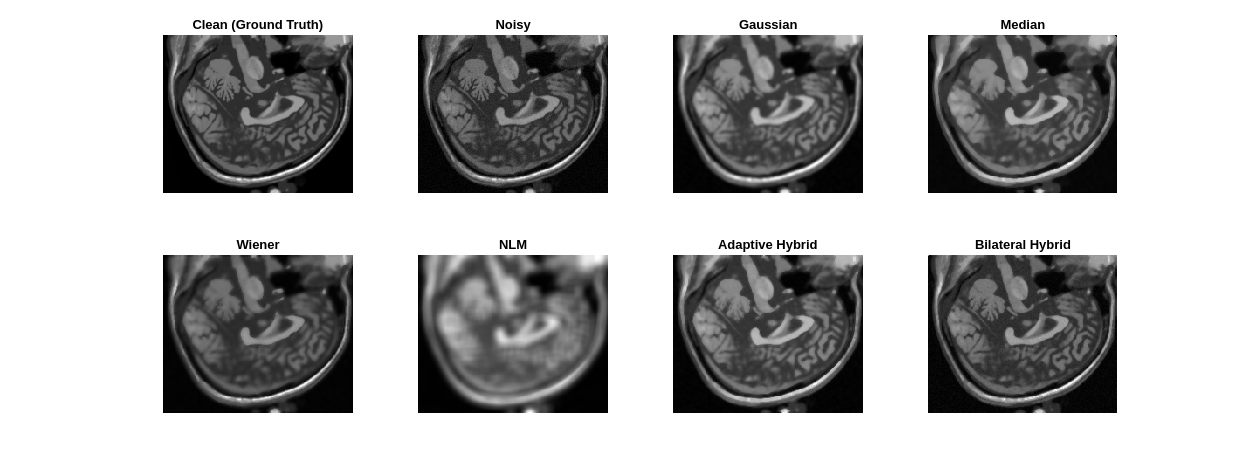


Processing t1_icbm_normal_1mm_pn5_rf0.nii...


Adaptive params → w=7 | σ=0.60 | v=1.20


Bilateral params → sp=5 | int=35 | thr=0.010


PSNR → G=25.026 | M=22.203 | W=30.109 | NLM=16.985 | A=24.146 | B=31.563


SSIM → G=0.820 | M=0.743 | W=0.777 | NLM=0.486 | A=0.765 | B=0.809


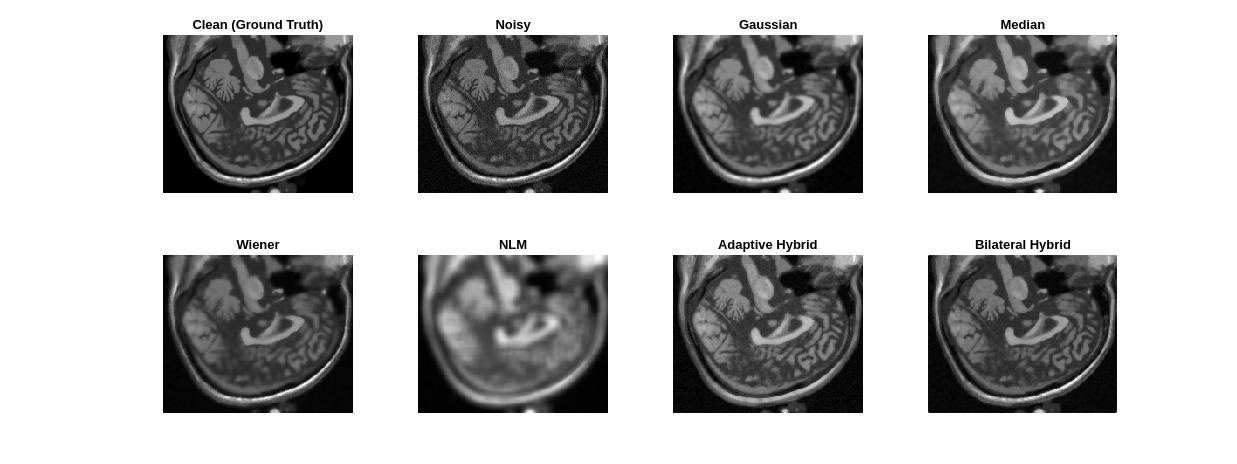


Processing t1_icbm_normal_1mm_pn9_rf0.nii...


Adaptive params → w=5 | σ=1.40 | v=1.20


Bilateral params → sp=2 | int=15 | thr=0.010


PSNR → G=25.688 | M=23.123 | W=25.715 | NLM=17.114 | A=26.708 | B=28.193


SSIM → G=0.772 | M=0.697 | W=0.717 | NLM=0.446 | A=0.767 | B=0.735


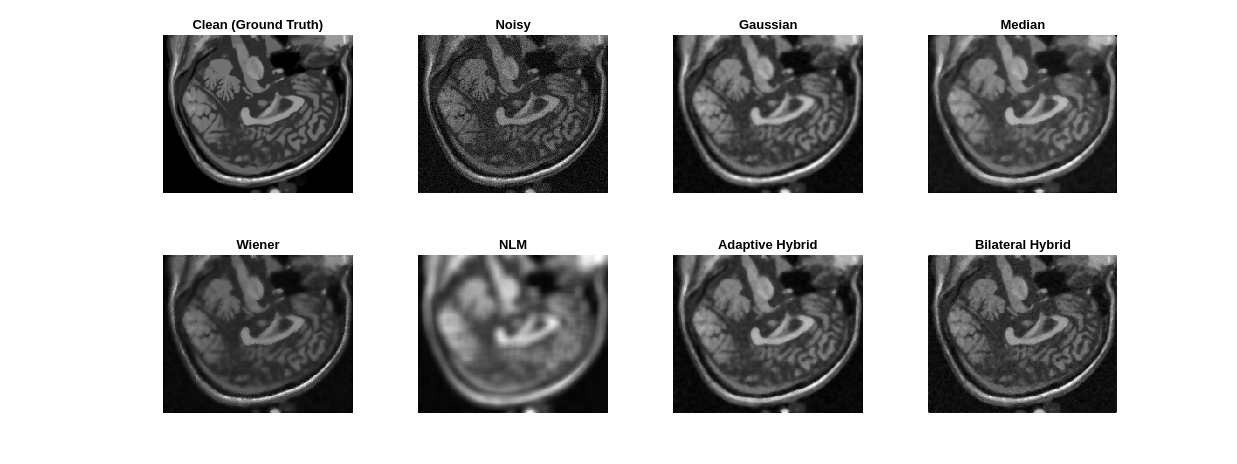

% LOOP THROUGH NOISY IMAGES

for i = 1:length(files)
    
    noisy_name = files{i};
    fprintf("\nProcessing %s...\n", noisy_name);

    noisy_vol = load_brainweb_nifti(fullfile(dataDir, noisy_name));

    % Raw + normalized noisy slice
    noisy_slice_raw = double(noisy_vol(:,:,slice_idx));
    noisy_slice     = mat2gray(noisy_slice_raw);

    % BASELINE SPATIAL FILTERS (on normalized noisy_slice)

    % Gaussian
    gFilt = mat2gray(imgaussfilt(noisy_slice, 1.2));

    % Median
    mFilt = mat2gray(medfilt2(noisy_slice, [5 5]));

    % Wiener
    wFilt = mat2gray(wiener2(noisy_slice, [5 5]));

    % NLM (MATLAB built-in)
    nlmFilt = mat2gray(imnlmfilt(noisy_slice, ...
                'SearchWindowSize', 11, ...
                'ComparisonWindowSize', 3, ...
                'DegreeOfSmoothing', 1));

    % ADAPTIVE HYBRID FILTER (Gaussian + Median)

    switch noisy_name
        case "t1_icbm_normal_1mm_pn3_rf0.nii"
            winSize    = 5;
            gaussSigma = 1.0;
            varFactor  = 1.2;

        case "t1_icbm_normal_1mm_pn5_rf0.nii"
            winSize    = 7;
            gaussSigma = 0.6;
            varFactor  = 1.2;

        case "t1_icbm_normal_1mm_pn9_rf0.nii"
            winSize    = 5;
            gaussSigma = 1.4;
            varFactor  = 1.2;
    end

    fprintf("Adaptive params → w=%d | σ=%.2f | v=%.2f\n", ...
            winSize, gaussSigma, varFactor);

    adaptive_raw = adaptive_hybrid_filter(noisy_slice, winSize, gaussSigma, varFactor);
    adaptiveFilt = mat2gray(adaptive_raw);

    % BILATERAL HYBRID FILTER

    % Best parameters from sweep
    switch noisy_name
        case "t1_icbm_normal_1mm_pn3_rf0.nii"
            sigmaSpatial   = 5;
            sigmaIntensity = 35;
            edgeThresh     = 0.030;

        case "t1_icbm_normal_1mm_pn5_rf0.nii"
            sigmaSpatial   = 5;
            sigmaIntensity = 35;
            edgeThresh     = 0.010;

        case "t1_icbm_normal_1mm_pn9_rf0.nii"
            sigmaSpatial   = 2;
            sigmaIntensity = 15;
            edgeThresh     = 0.010;
    end

    fprintf("Bilateral params → sp=%d | int=%d | thr=%.3f\n", ...
            sigmaSpatial, sigmaIntensity, edgeThresh);

    % IMPORTANT: run on RAW image, then normalize for metrics/visuals
    bilateral_raw = bilateral_hybrid_filter( ...
                        noisy_slice_raw, ...
                        sigmaSpatial, ...
                        sigmaIntensity, ...
                        edgeThresh);

    bilateralFilt = mat2gray(bilateral_raw);

    % METRICS (PSNR, SSIM, RMSE) – all vs normalized ref_slice

    g_psnr   = psnr(gFilt,        ref_slice);
    m_psnr   = psnr(mFilt,        ref_slice);
    w_psnr   = psnr(wFilt,        ref_slice);
    nlm_psnr = psnr(nlmFilt,      ref_slice);
    a_psnr   = psnr(adaptiveFilt, ref_slice);
    b_psnr   = psnr(bilateralFilt, ref_slice);

    g_ssim   = ssim(gFilt,        ref_slice);
    m_ssim   = ssim(mFilt,        ref_slice);
    w_ssim   = ssim(wFilt,        ref_slice);
    nlm_ssim = ssim(nlmFilt,      ref_slice);
    a_ssim   = ssim(adaptiveFilt, ref_slice);
    b_ssim   = ssim(bilateralFilt, ref_slice);

    g_rmse   = sqrt(immse(gFilt,        ref_slice));
    m_rmse   = sqrt(immse(mFilt,        ref_slice));
    w_rmse   = sqrt(immse(wFilt,        ref_slice));
    nlm_rmse = sqrt(immse(nlmFilt,      ref_slice));
    a_rmse   = sqrt(immse(adaptiveFilt, ref_slice));
    b_rmse   = sqrt(immse(bilateralFilt, ref_slice));

    % Print summary for this file
    fprintf("PSNR → G=%.3f | M=%.3f | W=%.3f | NLM=%.3f | A=%.3f | B=%.3f\n", ...
            g_psnr, m_psnr, w_psnr, nlm_psnr, a_psnr, b_psnr);

    fprintf("SSIM → G=%.3f | M=%.3f | W=%.3f | NLM=%.3f | A=%.3f | B=%.3f\n", ...
            g_ssim, m_ssim, w_ssim, nlm_ssim, a_ssim, b_ssim);

    % Append to metrics table
    metric_rows(end+1,:) = {noisy_name, "Gaussian",  g_psnr, g_ssim, g_rmse};
    metric_rows(end+1,:) = {noisy_name, "Median",    m_psnr, m_ssim, m_rmse};
    metric_rows(end+1,:) = {noisy_name, "Wiener",    w_psnr, w_ssim, w_rmse};
    metric_rows(end+1,:) = {noisy_name, "NLM",       nlm_psnr, nlm_ssim, nlm_rmse};
    metric_rows(end+1,:) = {noisy_name, "Adaptive",  a_psnr, a_ssim, a_rmse};
    metric_rows(end+1,:) = {noisy_name, "Bilateral", b_psnr, b_ssim, b_rmse};

    %% SAVE OUTPUTS (individual filter images)

    fn = erase(noisy_name, ".nii");

    imwrite(gFilt,         fullfile(figuresDir, fn + "_gaussian.png"));
    imwrite(mFilt,         fullfile(figuresDir, fn + "_median.png"));
    imwrite(wFilt,         fullfile(figuresDir, fn + "_wiener.png"));
    imwrite(nlmFilt,       fullfile(figuresDir, fn + "_nlm.png"));
    imwrite(adaptiveFilt,  fullfile(figuresDir, fn + "_adaptive.png"));
    imwrite(bilateralFilt, fullfile(figuresDir, fn + "_bilateral.png"));

    %% VISUAL SUMMARY FIGURE
    % Layout: 2x4
    % Row 1: Clean | Noisy | Gaussian | Median
    % Row 2: Wiener | NLM | Adaptive | Bilateral

    figure('Position',[200 200 1600 600]);

    subplot(2,4,1); imshow(ref_slice,[]);       title("Clean (Ground Truth)");
    subplot(2,4,2); imshow(noisy_slice,[]);     title("Noisy");
    subplot(2,4,3); imshow(gFilt,[]);           title("Gaussian");
    subplot(2,4,4); imshow(mFilt,[]);           title("Median");

    subplot(2,4,5); imshow(wFilt,[]);           title("Wiener");
    subplot(2,4,6); imshow(nlmFilt,[]);         title("NLM");
    subplot(2,4,7); imshow(adaptiveFilt,[]);    title("Adaptive Hybrid");
    subplot(2,4,8); imshow(bilateralFilt,[]);   title("Bilateral Hybrid");

    saveas(gcf, fullfile(figuresDir, fn + "_summary.png"));

end


fprintf("\nPhase 3 complete.\n");


Phase 3 complete.



% SAVE METRICS TO CSV
metric_tbl = cell2table(metric_rows, ...
    'VariableNames', {'NoiseFile','Filter','PSNR','SSIM','RMSE'});

outputPath = fullfile(metricsDir, "phase3_metrics.csv");
writetable(metric_tbl, outputPath);

fprintf("Saved metrics to %s\n", outputPath);

Saved metrics to ./results/metrics/phase3_metrics.csv
